
close all;
flute = "C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\429064__carloscarty__dizi-flute-loop-21-120-bpm.wav";
[y, Fs] = audioread(flute);
y = y * 1.75;
max(abs(y))

ans = 0.9992

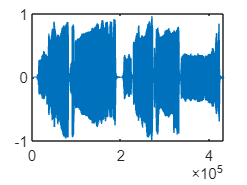

orginal = audioplayer(y, Fs);


%orginal.play;

%f1 = figure;
%subplot(211)
% orginal ska det egentligen vara 
%subplot(212)


% ---- Speed = 1 orginal temp, speed = 0.5 halva osv

speed = 2;
windowSize = round(1 * 0.05 * Fs);
stepSize = round(windowSize * speed);

newFrame = zeros(round(length(orginal) * (windowSize / stepSize) + windowSize), 1);
k = 1;
for i = (0:stepSize:length(y) - 1)
    for j = (0:1:windowSize -1)

        newFrame(k) = i + j + 1;
        k = k + 1;

    end
end

ix = newFrame > 0;
newFrame = newFrame(ix);

ix = newFrame <= length(y);
newFrame = newFrame(ix);

phaseVocodedSound = y(newFrame);

mixsound = audioplayer(phaseVocodedSound, Fs);
%mixsound.play;

plot(y)

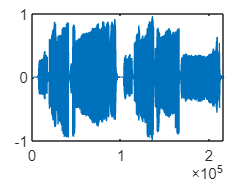

plot(phaseVocodedSound)



%-------- Pitch

pitch = 0.5;
Fs2 = Fs * pitch;

mixsoundpitch = audioplayer(phaseVocodedSound, Fs2);
%mixsoundpitch.play

% ----------Granularsyntes

grainSize = 0.1; % fönsterstorleken
speedFactor = 0.5; % hastighet
numberRepeats = 2; % upprepar fönseterna i följd

frameSize = floor(grainSize * Fs);
decomposeHopLength = round(grainSize * frameSize);
numFrames = floor((length(y) - frameSize + decomposeHopLength) / decomposeHopLength);

frameMatrix = zeros(frameSize, numFrames);

for currentFrame = (1:decomposeHopLength:length(y) - frameSize)
    thisFrame = y(currentFrame:currentFrame+frameSize-1);
    
    frameMatrix(:, round(currentFrame/decomposeHopLength) + 1) = thisFrame.*hanning(frameSize);
    
   
end

reconstructHopLength = round(speedFactor * decomposeHopLength);
reconstructedSound = zeros(1, length(y) * numberRepeats * max(1, speedFactor));

countingFrames = 1;
for currentFrame = (1:1:numFrames)
    for i = (1:1:numberRepeats)
        startIndex = (countingFrames - 1) * reconstructHopLength + 1;
        stopIndex = (countingFrames - 1) * reconstructHopLength + frameSize;
        orginalSoundIndex = startIndex : stopIndex;
        
        reconstructedSound(orginalSoundIndex) = reconstructedSound(orginalSoundIndex) + frameMatrix(:,currentFrame)';
        countingFrames = countingFrames +1;

    end

end

reconstructedSound = reconstructedSound(1:find(reconstructedSound, 1, 'last'));
reconstructedSound = reconstructedSound * 0.0923;
max(abs(reconstructedSound))

ans = 0.7117

mixsound2 = audioplayer(reconstructedSound, Fs);
mixsound2.play

%------ Baklänges
grainSize = 0.5; % fönsterstorleken
speedFactor = 2; % hastighet
numberRepeats = 1; % upprepar fönseterna i följd

frameSize = floor(grainSize * Fs);
decomposeHopLength = round(grainSize * frameSize);
numFrames = floor((length(y) - frameSize + decomposeHopLength) / decomposeHopLength);

frameMatrix = zeros(frameSize, numFrames);

for currentFrame = (1:decomposeHopLength:length(y) - frameSize)
    thisFrame = y(currentFrame:currentFrame+frameSize-1);
    
    frameMatrix(:, round(currentFrame/decomposeHopLength) + 1) = flipud(thisFrame.*hanning(frameSize));
    
   
end

reconstructHopLength = round(speedFactor * decomposeHopLength);
reconstructedSound = zeros(1, length(y) * numberRepeats * max(1, speedFactor));

countingFrames = 1;
for currentFrame = (1:1:numFrames)
    for i = (1:1:numberRepeats)
        startIndex = (countingFrames - 1) * reconstructHopLength + 1;
        stopIndex = (countingFrames - 1) * reconstructHopLength + frameSize;
        orginalSoundIndex = startIndex : stopIndex;
        
        reconstructedSound(orginalSoundIndex) = reconstructedSound(orginalSoundIndex) + frameMatrix(:,currentFrame)';
        countingFrames = countingFrames +1;

    end

end

reconstructedSound = reconstructedSound(1:find(reconstructedSound, 1, 'last'));
reconstructedSound = fliplr(reconstructedSound * 1.1);
max(abs(reconstructedSound))

ans = 1.0287

mixsound2 = audioplayer(reconstructedSound, Fs);
mixsound2.stop


ans =

     []



grainSize = 0.4; % fönsterstorleken
speedFactor = 1.5; % hastighet
numberRepeats = 1; % upprepar fönseterna i följd

frameSize = floor(grainSize * Fs);
decomposeHopLength = round(grainSize * frameSize);
numFrames = floor((length(y) - frameSize + decomposeHopLength) / decomposeHopLength);
randFrames = randperm(numFrames - 1);

frameMatrix = zeros(frameSize, numFrames);

for currentFrame = (1:decomposeHopLength:length(y) - frameSize)
    thisFrame = y(currentFrame:currentFrame+frameSize-1);
    
    frameMatrix(:, round(currentFrame/decomposeHopLength) + 1) = thisFrame.*hanning(frameSize);
    
   
end

reconstructHopLength = round(speedFactor * decomposeHopLength);
reconstructedSound = zeros(1, length(y) * numberRepeats * max(1, speedFactor));

countingFrames = 1;
for currentFrame = (1:1:numFrames)
    for i = (1:1:numberRepeats)
        startIndex = (randFrames(countingFrames) - 1) * reconstructHopLength + 1;
        stopIndex = (randFrames(countingFrames) - 1) * reconstructHopLength + frameSize;
        orginalSoundIndex = startIndex : stopIndex;
        
        reconstructedSound(orginalSoundIndex) = reconstructedSound(orginalSoundIndex) + frameMatrix(:,currentFrame)';
        
        if (countingFrames <= length(randFrames) -1)

            countingFrames = countingFrames + 1;

        end
        

    end

end



reconstructedSound = reconstructedSound(1:find(reconstructedSound, 1, 'last'));

minA = min(reconstructedSound(:)); % Minimivärde i matrisen
maxA = max(reconstructedSound(:)); % Maximivärde i matrisen

A_norm = 2 * ((reconstructedSound - minA) / (maxA - minA)) - 1;

% Pitch
Fs2 = Fs * speedFactor;

mixsound2 = audioplayer(A_norm, Fs);
mixsound2.play